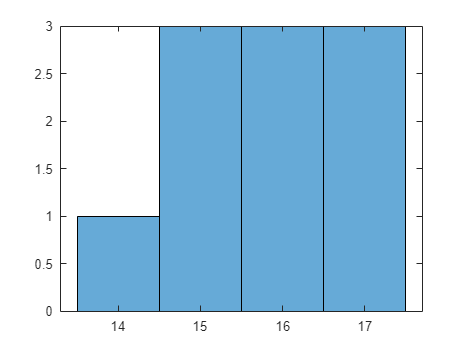

% ================ 注释中英文对照，供阅读比较================
% 控制树的深度
% 您可以使用 MaxNumSplits、MinLeafSize 或 MinParentSize 名称-值对参数。
% fitctree 默认生长深度决策树。
% 您可以种植更浅的树以减少模型复杂性或计算时间。
% Control Tree Depth
% You can control the depth of the trees using the MaxNumSplits, MinLeafSize, 
% or MinParentSize name-value pair parameters.  
% fitctree grows deep decision trees by default. 
% You can grow shallower trees to reduce model complexity or computation time.

%  加载电离层数据集
% Load the ionosphere data set.
load ionosphere

% ============= Model Set 1 ： MdlDefault ===========
% 用于控制生长fitctree分类树的默认值是：
% n - 1 表示 MaxNumSplits。 n 是训练样本大小。
% 1 为 MinLeafSize。
% 10 为 MinParentSize。
% 这些默认值倾向于为大的训练样本量生长深树。
% The default values of the tree depth controllers for growing classification trees are:
% n - 1 for MaxNumSplits. n is the training sample size.
% 1 for MinLeafSize.
% 10 for MinParentSize.
% These default values tend to grow deep trees for large training sample sizes.

% 使用fitctree树深度控制的默认值训练分类树。
% 使用 10 折交叉验证对模型进行交叉验证。
% Train a classification tree using the default values for tree depth control.
% Cross-validate the model by using 10-fold cross-validation.
rng(1); % For reproducibility

% 'CrossVal','on'打开以后，fitctree会训练生成多个树，默认是10折交叉检验，所以是10个树
% 10个树存储在MdlDefault.Trained，比如第一课树是MdlDefault.Trained{1}
MdlDefault = fitctree(X,Y,'CrossVal','on');


% 绘制10颗树分配的分支个数的直方图。
% 使用了cellfun函数，其功能介绍如下：
% A = cellfun(func,C) 将函数 func 应用于元胞数组 C 的每个元胞的内容，每次应用于一个元胞。
% 然后 cellfun 将 func 的输出串联成输出数组 A
% Draw a histogram of the number of imposed splits on the trees. Also, view one of the trees.
numBranches = @(x)sum(x.IsBranch);
mdlDefaultNumSplits = cellfun(numBranches, MdlDefault.Trained);

figure;
% 查看10课树在不同分支个数下的树的个数
% 横轴是分支个数，这里是14 15 16 17
% 纵轴是树的个数，这里是1，3，3，3个
histogram(mdlDefaultNumSplits)

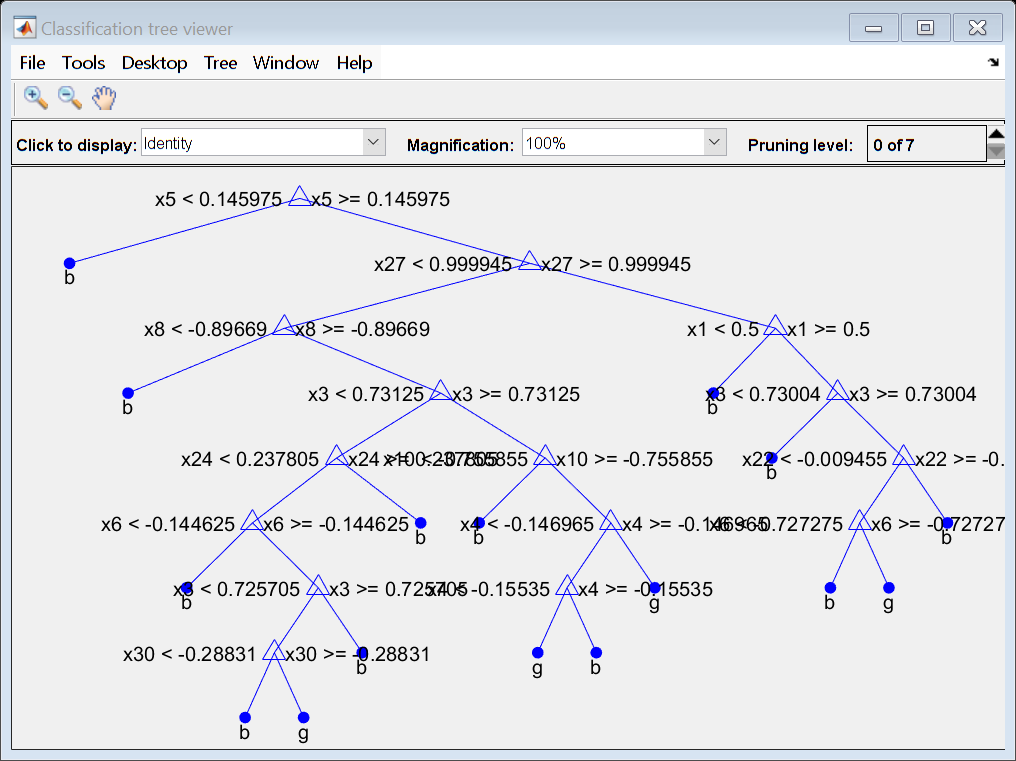


% 查看第一课树是MdlDefault.Trained{1}
view(MdlDefault.Trained{1},'Mode','graph')

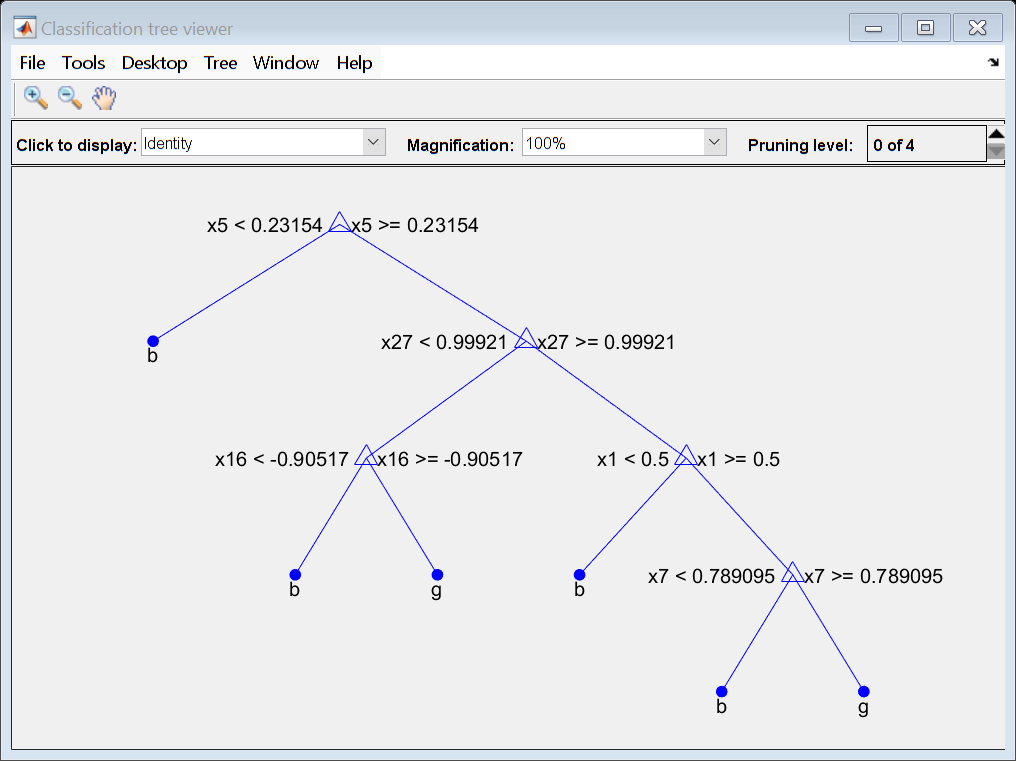

% The average number of splits is around 15.

% ============= Model Set 2 ： Mdl7 ===========
% 假设你想要一个没有使用默认分割数训练的那么复杂（深）的分类树
% 训练另一个分类树，将最大分割数设置为 7，大约是平均分割数的一半
% 来自默认分类树。 使用 10 折交叉验证对模型进行交叉验证。
% Suppose that you want a classification tree that is not as complex (deep) as
% the ones trained using the default number of splits. Train another classification tree, 
% but set the maximum number of splits at 7, which is about half the mean number of splits
% from the default classification tree. Cross-validate the model by using 10-fold cross-validation.

% 'CrossVal','on'打开以后会训练生成多个树，默认是10折交叉检验，所以是10个树
Mdl7 = fitctree(X,Y,'MaxNumSplits',7,'CrossVal','on');
view(Mdl7.Trained{1},'Mode','graph') % 把第一个树拿出来看看


% 比较2套模型（每个是10个模型）的交叉验证分类错误。
% Compare the cross-validation classification errors of the models.
classErrorDefault = kfoldLoss(MdlDefault)

classErrorDefault = 0.1168

classError7 = kfoldLoss(Mdl7)

classError7 = 0.1311


% 整体上，Mdl7 的复杂性要低得多，而且性能仅比 MdlDefault 稍差。
% Mdl7 is much less complex and performs only slightly worse than MdlDefault.